%% Simulation of linear system of monocopter with flaps
J = 3.2284E-6; % moment of inertia of the rotor
b = 3.5077E-6; % motor viscous friction constant 
K = 0.0274; % electromotive force constant, motor torque constant 
R = 4; % electric resistance 
L = 2.75E-6; % electric inductance  
Jxx = 0.00099;
Jzz = 0.001;
pitch = 41;
pitch = abs(pitch);
ka = 20; % tentative number
cl = 0.11 * pitch * ka;
rps_section = 1/(-22^2);
g = 9.81;
rho = 1.225;
radius = 0.61;
chord_length = 0.1;
torque_w_mass = radius*((cl*rho*chord_length*(radius^3))/(6));
omega_dot = torque_w_mass/Jxx;
s = tf('s');
servo = K/(s*((J*s+b)*(L*s+R)+K^2)); % includes the integral to positional angle alrd
H_servo = 1;
H_omega_dot_tf = 1; % lpf is needed and tuned here for indi, ndi is better only  
stf = servo/(1+(servo*H_servo));
%isstable(stf)
%pole(stf)
%omega_dot_tf = stf; % ndi
omega_dot = stf*omega_dot;
% omega_dot_tf = omega_dot/(1+(omega_dot*H_omega_dot_tf)); % indi
% isstable(omega_dot_tf)
% pole(omega_dot_tf)

[omega_dot_controller,info] = pidtune(omega_dot,'PID')

omega_dot_controller =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.0079, Ki = 0.243, Kd = 6.43e-05
 
Continuous-time PID controller in parallel form.
Model Properties


info = struct with fields:
                Stable: 1
    CrossoverFrequency: 64.4256
           PhaseMargin: 64.7364


omega_dot_tf = feedback(omega_dot_controller*omega_dot,1); % implement feedback for tf which is servo to become servo/(1+(servo*H)

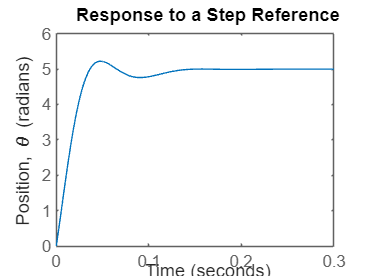

% to simulate step input of a single servo angle
t = 0:0.001:0.3;
Config = RespConfig('Amplitude',5);
step(omega_dot_tf, t, Config) % step function here is in the form of a servo angle 
ylabel('Position, \theta (radians)')
title('Response to a Step Reference')

%legend('Kp = 1',  'Kp = 11',  'Kp = 21')

%% to simulate disturbance step input

% [omega_dot_pi,info_d] = pidtune(stf*torque_w_mass,'PID')
% disturbance_torque_tf = ((1/Jxx)*(1-(H_omega_dot_tf*omega_dot_pi*stf*torque_w_mass)));
% t = 0:0.001:0.2;
% Config = RespConfig('Amplitude',5);
% step(disturbance_torque_tf, t, Config) % step function here is in the form of a servo angle 
% ylabel('omega_dot_tf')
% title('Response to a Step Disturbance')

%% to simulate step input to isolate precession portion and vertical rotation rate
% hz = 5.6;
% rps = hz * 2 * pi * -1;
% H_precession = Jxx/(Jzz*-22) % dampener, precession inner loop
% H_precession = 0;
% precession_tf = omega_dot_tf/(1-(omega_dot_tf*H_precession)); % indi
precession_tf = omega_dot_tf;
% t = 0:0.001:0.3;
% Config = RespConfig('Amplitude',5);
% step(precession_tf, t, Config) % step function here is in the form of a servo angle 
% ylabel('radians/seconds')
% title('Response to a Step Reference')

%% find the lift force to hold alt 
g = 9.81;
cd = 0.093; %0.023;
rho = 1.225;
radius = 0.61;
pitch = 41;
pitch = abs(pitch);
mass = 0.16;
cd = cd * pitch; % gradient for cd taken from naca 0006, pitch must be in deg
chord_length = 0.1;
omega_z_body = -22; % the lower the btr apparently
rps = omega_z_body;
drag_rotation = 1*(cd*(omega_z_body^2)*rho*chord_length*(radius^3))/(6*mass);
com = 1/(-(g + drag_rotation));
%com = -1;

H_q = 1;
H_omega = 1;
H_a = 1;

kp_omega = 100; % input 2 is jerk control 
kd_omega = 100; 
kp_q = 850; % input 3 quartenion control
D = 3; % input 2 is jerk control, dun make much of a difference
snap_coeff = 1;
% input 1 is snap control 

% snap + jerk
omega = (s+D)*com*omega_dot*(1/(s^2))*1/com; % jerk only
%omega_controller = kp_omega + kd_omega*s;
[omega_controller,omega_info] = pidtune(omega,'PID',300)

omega_controller =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1.72, Ki = 4.52, Kd = 0.164
 
Continuous-time PID controller in parallel form.
Model Properties


omega_info = struct with fields:
                Stable: 1
    CrossoverFrequency: 300
           PhaseMargin: 8.8400


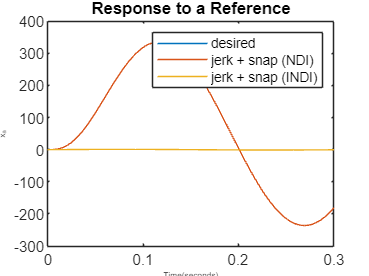

omega_tf_ndi = (omega_controller*omega)+((s^2)*com*omega_dot*(1/(s^2))*1/com); % jerk and snap NDI
omega_tf = feedback((omega_controller*omega)+((s^2)*com*omega_dot*(1/(s^2))*1/com),1); % jerk and snap INDI

t = 0:0.001:0.3;
u = sin(20*t);
jerk_and_snap = lsim(omega_tf,u,t);
jerk_and_snap_ndi = lsim(omega_tf_ndi,u,t);
plot (t,u)
hold on
plot(t,jerk_and_snap_ndi)
plot(t,jerk_and_snap)
hold off

ylabel('x_a','FontSize',5)
xlabel('Time(seconds)','FontSize',5)
title('Response to a Reference','FontSize',10)
legend('desired','jerk + snap (NDI)','jerk + snap (INDI)')

% quat, for this to work, resume normal number and switch to pid 
angle = com*omega_dot*(1/(s^2))*1/com;
[angle_controller,angle_info] = pidtune(angle,'PID',19)

angle_controller =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.0483, Ki = 0.00803, Kd = 0.0726
 
Continuous-time PID controller in parallel form.
Model Properties


angle_info = struct with fields:
                Stable: 1
    CrossoverFrequency: 19
           PhaseMargin: 55.4138


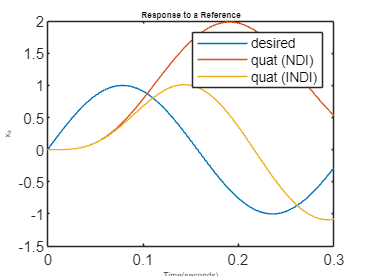

angle_tf = feedback(angle_controller*angle,1);
angle_tf_ndi = angle_controller*angle;

t = 0:0.001:0.3;
u = sin(20*t);
quat = lsim(angle_tf,u,t);
quat_ndi = lsim(angle_tf_ndi,u,t);
plot (t,u)
hold on
plot(t,quat_ndi)
plot(t,quat)
hold off

ylabel('x_a','FontSize',5)
xlabel('Time(seconds)','FontSize',5)
title('Response to a Reference','FontSize',5)
legend('desired','quat (NDI)','quat (INDI)')

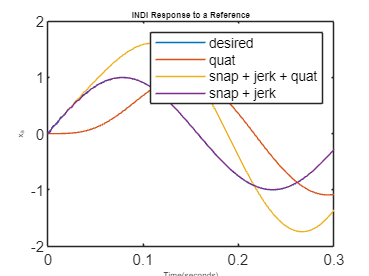

t = 0:0.001:0.3;
u = sin(20*t);
plot (t,u)
hold on
plot(t,quat)
plot(t,jerk_and_snap+quat)
plot(t,jerk_and_snap) % no quat here = the best
hold off

ylabel('x_a','FontSize',5)
xlabel('Time(seconds)','FontSize',5)
title('INDI Response to a Reference','FontSize',5)
legend('desired','quat','snap + jerk + quat','snap + jerk')

% conclusion: maybe the single motor vs w flap wud help  

% % numerator = precession_tf*Jzz*rps*com*((s^2)+(s*kp_omega)+(D*kp_omega)+kp_q);
% numerator = [(snap_coeff*precession_tf*Jzz*rps*com),precession_tf*Jzz*rps*com*kp_omega,precession_tf*Jzz*rps*com*((D*kp_omega)+kp_q)];
% % denominator = (com((s^2)*((Jzz*rps)+(Jxx*precession_tf*H_disturbance_p))+(s*H_omega*precession_tf*kp_omega*Jzz*rps)+(precession_tf*kp_q*Jzz*rps*H_q))+(Jzz*rps*H_a*precession_tf));
% % denominator = [-1*com*Jxx*precession_tf*H_a,Jzz*rps,H_omega*precession_tf*kp_omega*Jzz*rps,(com*precession_tf*kp_q*Jzz*rps*H_q) + (Jzz*rps*H_a*precession_tf)]
% denominator = [com*Jzz*rps,com*H_omega*precession_tf*kp_omega*Jzz*rps,(com*precession_tf*kp_q*Jzz*rps*H_q) + (Jzz*rps*H_a*precession_tf)]
% a_tf = tf(numerator,denominator);
% 
% 
% t = 0:0.001:0.3;
% u = sin(20*t);
% Config = RespConfig('Amplitude',10);
% all_inputs = step(a_tf, t, Config); % step function here is in the form of a servo angle 
% % ylabel('x_a','FontSize',5)
% % xlabel('Time(seconds)','FontSize',5)
% % title('Response to a Step Reference','FontSize',5)
% 
% % isstable(a_tf)
% % pole(a_tf)
% % snap = all_inputs(:,:,1);
% % jerk = all_inputs(:,:,2);
% % quat = all_inputs(:,:,3);
% 
% snap = lsim(a_tf(1,1),u,t);
% % jerk = lsim(a_tf(1,2),u,t);
% % quat = lsim(a_tf(1,3),u,t);
% 
% total = snap + jerk + quat;
% plot (t,u)
% hold on
% plot(t,total)
% plot(t,quat)
% hold off
% 
% 
% ylabel('x_a','FontSize',5)
% xlabel('Time(seconds)','FontSize',5)
% title('Response to a Step Reference','FontSize',5)
% legend('desired','total','quat')